c = zeros(1,60);
c(1) = -1;
c(2) = 1;
r = c;
A = toeplitz(c, r)

A =     -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -1     1     0     0     0     0     0     0     0     0     0     0   


displayTopLeft_A = A(1:6, 1:6)

displayTopLeft_A =     -1     1     0     0     0     0
     1    -1     1     0     0     0
     0     1    -1     1     0     0
     0     0     1    -1     1     0
     0     0     0     1    -1     1
     0     0     0     0     1    -1



n = 1:60; %60 samples

% x1 = cos(0*n)' %not periodic
% subplot(4, 2, 1), stem(n, x1)
% title("x1")
% 
% x2 = cos(pi*n/6)' %period N = 12, normalized angular frequency = pi/6
% subplot(4, 2, 2), stem(n, x2)
% title("x2")

x3 = cos(pi*n/3)'; %period N = 6, normalized angular frequency = pi/3
x3' %aid display x3 transpose

ans =     0.5000   -0.5000   -1.0000   -0.5000    0.5000    1.0000    0.5000   -0.5000   -1.0000   -0.5000    0.5000    1.0000    0.5000   -0.5000   -1.0000   -0.5000    0.5000    1.0000    0.5000   -0.5000   -1.0000   -0.5000    0.5000    1.0000    0.5000   -0.5000   -1.0000   -0.5000    0.5000    1.0000    0.5000   -0.5000   -1.0000   -0.5000    0.5000    1.0000    0.5000   -0.5000   -1.0000   -0.5000    0.5000    1.0000    0.5000   -0.5000   -1.0000   -0.5000    0.5000    1.0000    0.5000   -0.5000


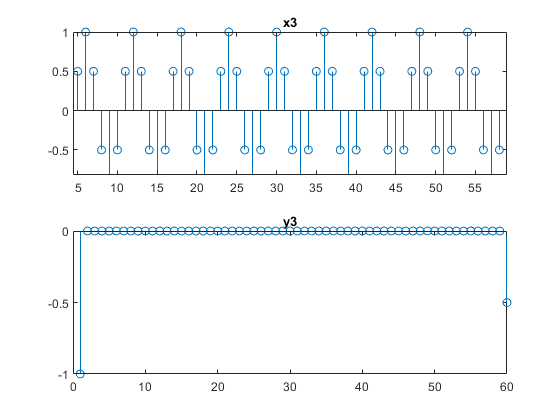

subplot(2, 1, 1), stem(n, x3)
title("x3")

% x4 = cos(pi*n/2)' %period N = 4, normalized angular frequency = pi/3
% subplot(4, 2, 4), stem(n, x4)
% title("x4")
% 
% y1 = A * x1
% subplot(4, 2, 5), stem(n, y1)
% title("y1")
% 
% y2 = A * x2
% subplot(4, 2, 6), stem(n, y2)
% title("y2")

y3 = A * x3;
subplot(2, 1, 2), stem(n, y3)
title("y3")


% y4 = A * x4
% subplot(4, 2, 8), stem(n, y4)
% title("y4")